% rng('default') % For reproducibility
% s = rng;
x = normrnd(0, 1, [1, 300])  % 50 random points between 0 and 5

x =     0.7502    2.0524   -0.3828   -0.7795   -0.1496    0.5419    0.7929   -0.7837    0.2930   -0.5472    0.0404   -0.4879   -0.5617    0.6198   -0.0549    0.1394   -0.0857    1.0760    0.5836    2.7124   -0.2200   -0.7563    0.4935   -0.5837   -0.1705   -0.3972    0.9815   -0.2396   -1.5933    1.3623   -1.4474    0.0143    0.5855   -0.2303   -0.0515    0.1341   -0.4182   -0.5323   -0.3650    0.3467    1.3252   -0.2062   -1.1940   -0.8936    0.5963    0.9984   -1.1701    0.1192   -1.0410   -0.0033


y = normrnd(0, 1, [1, 300])

y =    -3.0326    1.3780   -0.4862    0.0901   -0.4319   -0.9623    0.6621   -0.5751    0.9810    1.3732   -2.1247    0.3298    0.1003   -1.9607    0.7023    0.7008    0.4626    0.7699   -0.7909   -1.9329   -0.5490    0.7708    1.4810   -0.3721    1.1837    1.2804   -1.1960    0.4191    0.3656    0.9914   -0.2374   -1.7306   -0.5088   -0.3069   -1.0179    0.7002    0.0807   -0.0070    1.3788    0.3685    0.3833    0.2394    0.8612    0.3343    0.4065   -0.4792    0.8476   -1.1965    1.3860    0.3358


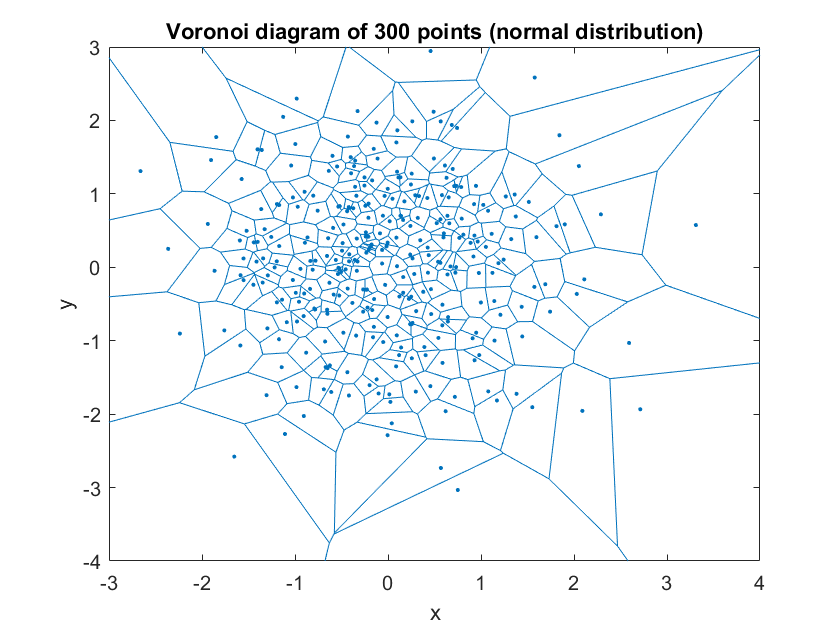

% x = new_x.';
% y = new_y.';
dt = delaunayTriangulation(x.', y.');
voronoi(x.', y.')
xlabel('x')
ylabel('y')
title('Voronoi diagram of 300 points (normal distribution)')
hold off


[V, r] = voronoiDiagram(dt);

V(1, :) = [];
N = size(x.', 1);   % N = 50

for i = 1:N
    r{i}(1, :) =  r{i}(1, :) - 1;
    r{i} = r{i}(r{i} ~= 0);     % eliminate 0 point, equivalent to Inf vertex
end

%neighbour matrix
vn = zeros(N, N);
for i = 1:N
    for j = 1:N
        if isConnected(dt, i, j)
            vn(i,j) = 1;
            vn(j,i) = 1;
        end
    end
end
vn2 = vn(:,:);

current_cell = randi([1 N], 1, 1);
visited = zeros(N, 1);

stack = java.util.Stack();
start = true;
nr = 0;

while ~stack.isEmpty() || start
    
    nr = nr + 1;
    start = false;
    
    neighbors = [];
    
    for i = 1:N
        if vn(current_cell, i) == 1 && visited(i) == 0
            neighbors = [neighbors; i];
        end
    end
    
    if isempty(neighbors)
        current_cell = stack.pop();
        continue;
    end
    
    ran = randi([1 size(neighbors, 1)], 1, 1);
    next_cell = neighbors(ran);
    %randsample(x, 1);
    
    vn(current_cell, next_cell) = 0;
    vn(next_cell, current_cell) = 0;
    
    stack.push(next_cell);
    
    current_cell = next_cell;
    visited(current_cell) = 1;
    
end

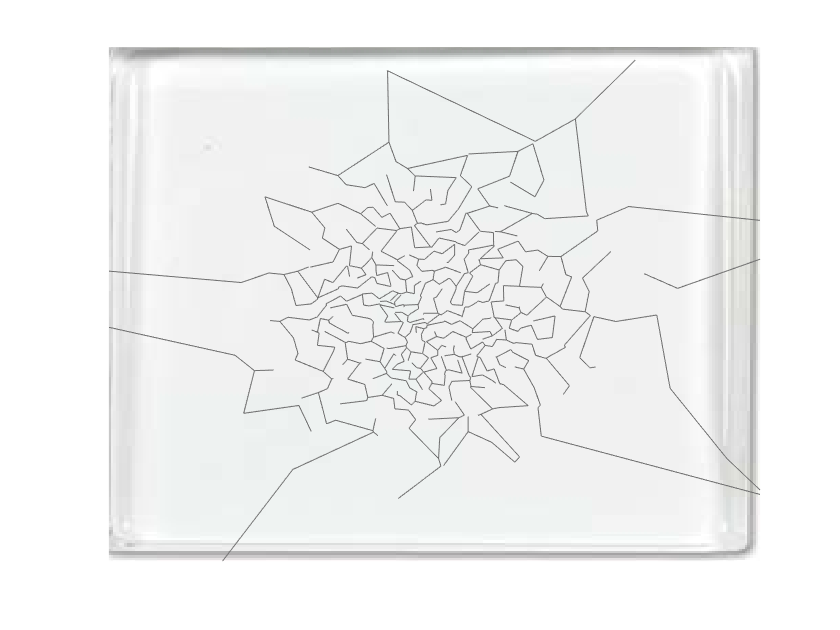

comm = [];
del = [];
for i = 1:N
    for j = 1:N
        if vn(i, j) == 1 && size(intersect(r{i}, r{j}), 2) == 2
            comm = [comm; intersect(r{i}, r{j})]; 
        end
    end
end


% new_x = x(del.');
% new_y = y(del.');
x_vor = V(:, 1);
y_vor = V(:, 2);
vx = x_vor(comm.');
vy = y_vor(comm.');

plot(vx, vy, 'Color', [112,112,112]/255) 
axis([-4 4 -4 4])
%'Color',  [0.30980  0.21176  0.16863], 'LineWidth', 1.5 0.57647  0.57255  0.69412
hold on
title('Normal distribution - Voronoi maze')
%set(gca,'Color', [0.70588  0.50196  0.40784])
set(gca, 'Visible', 'off')
% set(gca, 'YDir', 'reverse')
xlabel('x')
ylabel('y')
I = imread('\images\glass.jpg'); 
h = image([-5 5], [-5 5] ,I); 
set(gca, 'YDir', 'reverse');
uistack(h,'bottom')

% scatter(x, y, 'r.')
% plot(new_x, new_y, 'r-')

function x = randl(m, n)
% function: x  = randl(m, n)
% m - number of matrix rows
% n - number of matrix columns
% x - matrix with Laplacian distributed numbers 
%     with mu = 0 and sigma = 1 (columnwise)
% generation of two i.i.d. sequences
    u1 = rand(m, n);
    u2 = rand(m, n);
    % generation of a matrix with Laplacian
    % distributed numbers (columwise)
    x = log(u1./u2);
    x = bsxfun(@minus, x, mean(x));
    x = bsxfun(@rdivide, x, std(x));
end